EE3510 HW3 105060012張育菘

CP3.1 Determine a state variable representation for the following transfer functions (without feedback) using the SS function: 

(a) $G\left(s\right)=\frac{1}{s+10}$

close all; clear;

g1_num = [1]; g1_den = [1 10]; 
g1_tf = tf(g1_num, g1_den);
g1_ss = ss(g1_tf)


g1_ss =
 
  A = 
        x1
   x1  -10
 
  B = 
       u1
   x1   1
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



(b) $G\left(s\right)=\frac{s^2 +5s+3}{s^2 +8s+5}$ 

g2_num = [1 5 3]; g2_den = [1 8 5]; 
g2_tf = tf(g2_num, g2_den);
g2_ss = ss(g2_tf)


g2_ss =
 
  A = 
         x1    x2
   x1    -8  -2.5
   x2     2     0
 
  B = 
       u1
   x1   2
   x2   0
 
  C = 
         x1    x2
   y1  -1.5  -0.5
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.



(c) $G\left(s\right)=\frac{s+1}{s^3 +3s^2 +3s+1}$

g3_num = [1 1]; g3_den = [1 3 3 1]; 
g3_tf = tf(g3_num, g3_den);
g3_ss = ss(g3_tf)


g3_ss =
 
  A = 
         x1    x2    x3
   x1    -3  -1.5    -1
   x2     2     0     0
   x3     0   0.5     0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
        x1   x2   x3
   y1    0  0.5    1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



CP3.2 Determine a transfer function representation for the following state variable models using the tf function:

(a) $A=\left\lbrack \begin{array}{cc}
0 & 1\\
2 & 8
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack$

close all; clear;

a1 = [0 1; 2 8]; b1 = [0; 1]; 
c1 = [1 0]; d1 = [0];
sys1_ss = ss(a1, b1, c1, d1);
sys1_tf = tf(sys1_ss)


sys1_tf =
 
        1
  -------------
  s^2 - 8 s - 2
 
Continuous-time transfer function.



(b) $A=\left\lbrack \begin{array}{ccc}
1 & 1 & 0\\
-2 & 0 & 4\\
5 & 4 & -7
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
-1\\
0\\
1
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{ccc}
0 & 1 & 0
\end{array}\right\rbrack$ 

a2 = [1 1 0; -2 0 4; 5 4 -7]; b2 = [-1; 0; 1]; 
c2 = [0 1 0]; d2 = [0];
sys2_ss = ss(a2, b2, c2, d2);
sys2_tf = tf(sys2_ss)


sys2_tf =
 
         6 s - 10
  -----------------------
  s^3 + 6 s^2 - 21 s + 10
 
Continuous-time transfer function.



(c) $A=\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & -2
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{cc}
-2 & 1
\end{array}\right\rbrack$

a3 = [0 1; -1 -2]; b3 = [0; 1]; 
c3 = [-2 1]; d3 = [0];
sys3_ss = ss(a3, b3, c3, d3);
sys3_tf = tf(sys3_ss)


sys3_tf =
 
      s - 2
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



CP3.4 Consider the system


$$\dot{x} =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-3 & -2 & -5
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack u,y=\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack x$$


(a) Using the tf function, determine the transfer function Y(s)/U(s).

close all; clear;

a = [0 1 0; 0 0 1; -3 -2 -5]; b = [0; 0; 1]; 
c = [1 0 0]; d = [0];
sys_ss = ss(a, b, c, d);
sys_tf = tf(sys_ss)


sys_tf =
 
            1
  ---------------------
  s^3 + 5 s^2 + 2 s + 3
 
Continuous-time transfer function.



(b)  Plot the response of the system to the initial condition $x\left(0\right)={\left\lbrack \begin{array}{ccc}
0 & -1 & 1
\end{array}\right\rbrack }^T$ for $0\le t\le 10$.

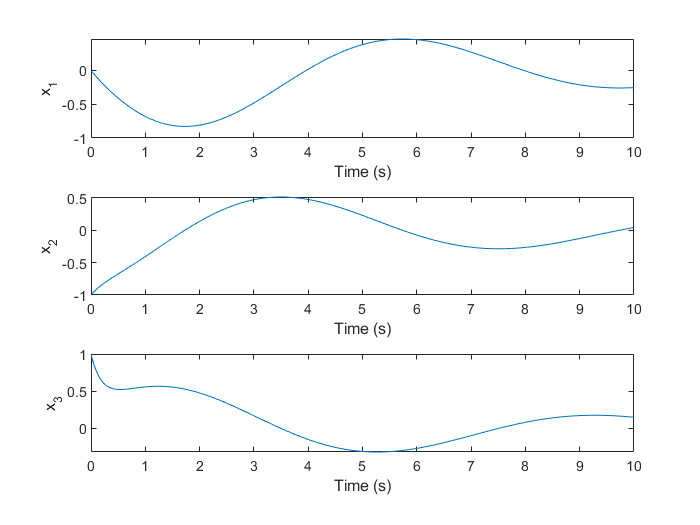

x0 = [0; -1; 1]; % initial condition
t = [0:0.01:10]; 
u = 0*t; % zero input

[y,T,x]=lsim(sys_ss,u,t,x0);
figure;
subplot(3,1,1); plot(T,x(:,1)); 
xlabel('Time (s)'); ylabel('x_1'); 
subplot(3,1,2); plot(T,x(:,2));
xlabel('Time (s)'); ylabel('x_2'); 
subplot(3,1,3); plot(T,x(:,3));
xlabel('Time (s)'); ylabel('x_3'); 

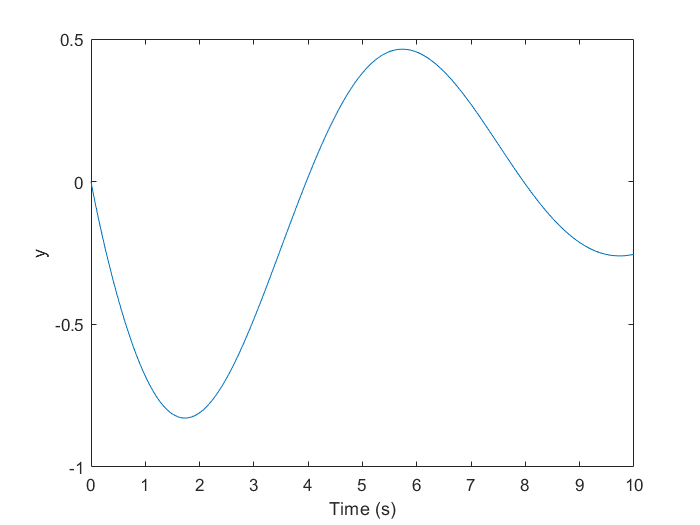

figure; plot(T,y);
xlabel('Time (s)'); ylabel('y'); 

(c)  Compute the state transition matrix using the expm function,and determine x(t) at t = 10 for the initial condition given in part (b). Compare the result with the system response obtained in part (b).

dt = 10;
phi = expm(a*dt);
fprintf("the result from part(c):");

the result from part(c):

x3 = phi*x0

x3 =    -0.2545
    0.0418
    0.1500


fprintf("the result from part(b):");

the result from part(b):

ans_b = x(1001,:)

ans_b =    -0.2545    0.0418    0.1500


We can find that the results from part (b) and part (c) are the same.

CP3.7 Consider the following system: $\dot{x} =\left\lbrack \begin{array}{cc}
0 & 1\\
-2 & -3
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack u,y=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack x,x\left(0\right)=\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack \ldotp$

Using the Isim function obtain and plot the system response (for x1(t) and x2(t)) when u(t) = 0. 

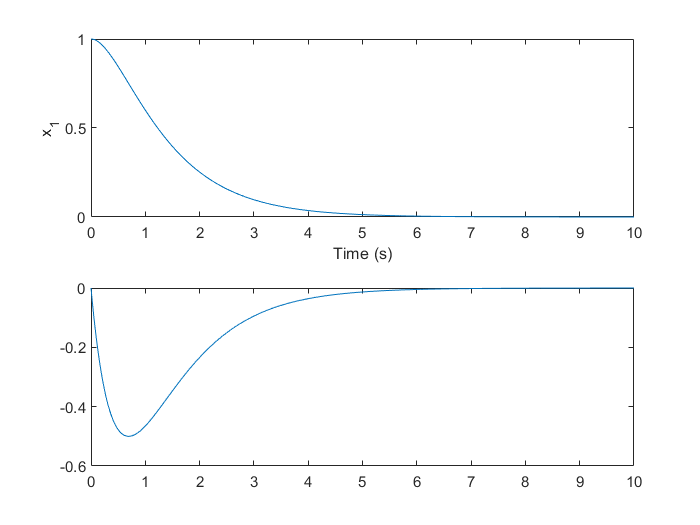

close all; clear;

a = [0 1; -2 -3]; b = [0; 1]; 
c = [1 0]; d = [0];
sys_ss = ss(a, b, c, d);

x0 = [1; 0]; % initial condition
t = [0:0.01:10]; 
u = 0*t; % zero input

[y,T,x]=lsim(sys_ss,u,t,x0);
figure;
subplot(2,1,1); plot(T,x(:,1)); 
xlabel('Time (s)'); ylabel('x_1'); 
subplot(2,1,2); plot(T,x(:,2));

CP3.8  Consider the state variable model with parameter K given by 


$$\dot{x} =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-2 & -K & -2
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack u,y=\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack x$$


Plot the characteristic values of the system as a function of K in the range $0\le K\le 100$. Determine that range of K for which all the characteristic values lie in the left half-plane. 

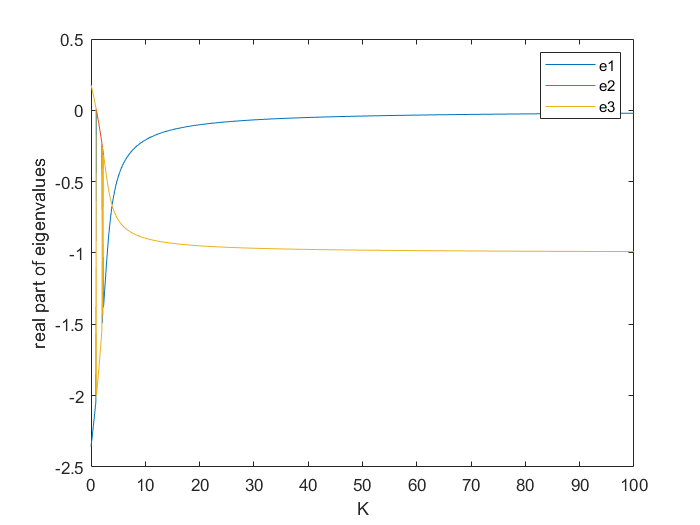

close all; clear;

dk = 0.1; K_fv = 100;
K = [0: dk: K_fv];
eigenA_real = zeros(3, (dk^-1)*K_fv+1);

i = 1;
for j = 0: dk: K_fv
    a = [0 1 0; 0 0 1; -2 -j -2]; 
    eigenA = eig(a);
    eigenA_real(:,i) = real(eigenA);
    i = i + 1;
end

figure; 
plot(K, eigenA_real(1,:)); hold on;
plot(K, eigenA_real(2,:));
plot(K, eigenA_real(3,:)); hold off;
xlabel('K'); ylabel('real part of eigenvalues');
legend(["e1"], ["e2"], ["e3"]);

We can find that all the characteristic values lie in the left half-plane in the range $1\le K\le 100$.